% AAE 532 HW 10 Problem 3
% Tomoki Koike
close all; clear all; clc;
fdir = 'C:\Users\Tomo\Desktop\studies\2020-Fall\AAE532\matlab\outputs\ps10';
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

% Set constants
planet_consts = setup_planetary_constants();  % Function that sets up all the constants in the table 
mars = planet_consts.mars;  % structure of mars
earth = planet_consts.earth;  % structure of earth
sun = planet_consts.sun;  % structure of sun
G = 6.6743015e-20;  % Gravitational constant [km^3/kg/s^2]

mu_sun = sun.gp  % gravitational parameter of sun

mu_sun = 1.3271e+11

mu_earth = earth.gp  % gravitational parameter of earth 

mu_earth = 3.9860e+05

mu_mars = mars.gp  % gravitational parameter of mars 

mu_mars = 4.2828e+04

R_mars = mars.mer  % radius of Mars

R_mars = 3397

R_earth = earth.mer  % radius of earth

R_earth = 6.3781e+03


r1 = earth.smao  % the first leg of the space triangle equal to the semi-major axis of earth

r1 = 149597898

r2 = mars.smao  % the second leg of the space triangle equal to the semi-major axis of mars

r2 = 227944135

v1 = sqrt(mu_sun / r1)  % initial velocity in the orbit of earth

v1 = 29.7847

v2 = sqrt(mu_sun / r2)  % final velocity in the orbit of mars

v2 = 24.1291


TrA = 120;  % transfer angle [deg]
c = sqrt(r1^2 + r2^2 - 2*r1*r2*cosd(TrA))  % chord length of the space triangle

c = 3.2930e+08

s = (r1 + r2 + c) / 2  % semi-perimeter 

s = 3.5342e+08

% TOF for parabolic orbit
TOF_para = lambertTOF_para(mu_sun, s, c, "1")

TOF_para = 8.4443e+06

TOF_para_days = TOF_para / 60 / 60 / 24

TOF_para_days = 97.7346

% Check which type of elliptical transfer
a_min = s/2  % the minimum possible semi-major axis of the transfer orbit

a_min = 1.7671e+08

alpha_o = 2*asin(sqrt(s / 2 / a_min))  % base alpha parameter

alpha_o = 3.1416

beta_o = 2*asin(sqrt((s - c) / 2 / a_min))  % base beta parameter

beta_o = 0.5286

 
% Calculate the minimum TOF using lambert equation
TOF_min = lambert_ellip(alpha_o, beta_o, mu_sun, "TOF", "1A", a_min) 

TOF_min = 2.0101e+07

TOF_min_days = TOF_min / 60 / 60 / 24

TOF_min_days = 232.6504

% Preallocate total DV vector 
Dv_tot_array = [];
% For loop to find the optimal TOF for given space triangle 
TOF_days_array = round(TOF_para_days)+1:TOF_min_days*3;
for TOF_days = TOF_days_array
    revert = 0;
    TOF = TOF_days * 60 * 60 * 24;  % TOF [s]
    if TOF > TOF_min
        type = "1B";
    else
        type = "1A";
    end
    % Find the SMA corresponding to the TOF
    [a, alpha, beta, fval] = find_lambertEllip_SMA(s, c, TOF, mu_sun, a_min, type);
    
    [p, e, TA_dep, TA_arr, p_db, TA_dep_db, TA_arr_db] = find_lambertX_ellip(a, alpha, ...
    beta, TrA, s, c, r1, r2, mu_sun, TOF_days, "day");
    
    % Calculate energy
    En = -mu_sun / 2 / a;
    % Velocity and FPA
    v_dep = vis_viva(r1, a, mu_sun);
    v_arr = vis_viva(r2, a, mu_sun);
    FPA_dep = acos_dbval(sqrt(mu_sun * p)/r1 / v_dep, "deg");
    FPA_arr = acos_dbval(sqrt(mu_sun * p)/r2 / v_arr, "deg");
    if TA_dep > 0
        FPA_dep = FPA_dep(FPA_dep > 0);
    else
        FPA_dep = FPA_dep(FPA_dep < 0);
    end
    if TA_arr > 0
        FPA_arr = FPA_arr(FPA_arr > 0);
    else
        FPA_arr = FPA_arr(FPA_arr < 0);
    end
    
    
    % Departure 
    Dv_dep = sqrt(v_dep^2 + v1^2 - 2 * v_dep * v1 * cosd(FPA_dep));
    % Arrival 
    Dv_arr = sqrt(v_arr^2 + v2^2 - 2 * v_arr * v2 * cosd(FPA_arr));
    % Total
    Dv_tot = Dv_dep + Dv_arr;
    if isempty(Dv_tot)
        Dv_tot_array = [Dv_tot_array, NaN];
    else
        Dv_tot_array = [Dv_tot_array, Dv_tot];
    end
end

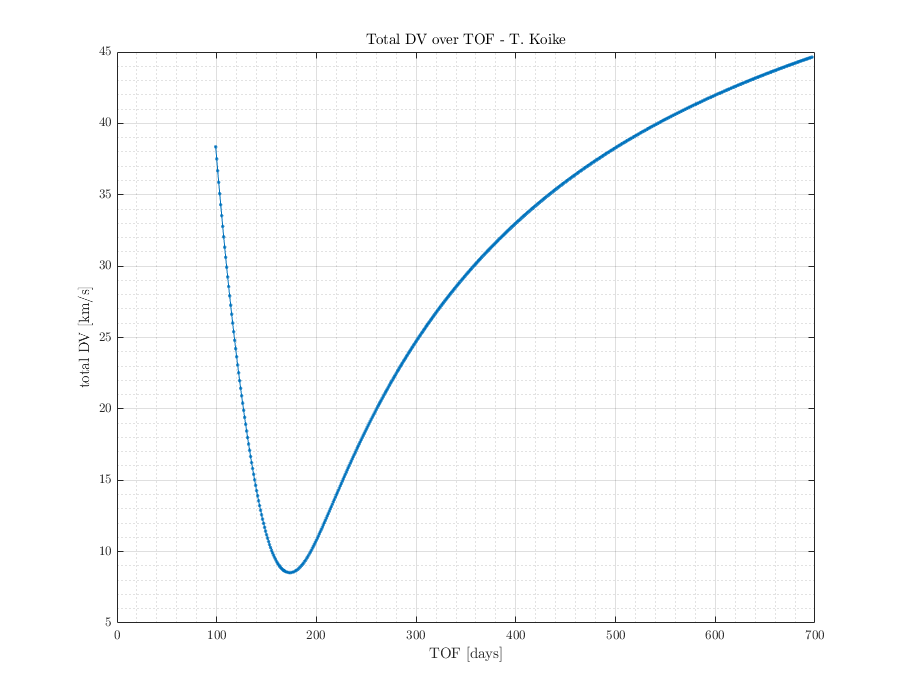

fig = figure("Renderer","painters","Position",[10 10 900 700]);
plot(TOF_days_array, Dv_tot_array, '.-')
grid on; grid minor; box on;
title('Total DV over TOF - T. Koike')
xlabel('TOF [days]')
ylabel('total DV [km/s]')

saveas(fig, fullfile(fdir, "p4_DV_TOF.png"));

% Find instance of minimal Dv
[Dv_tot_array_sort, idx] = sort(Dv_tot_array);
TOF_days_array_sort = TOF_days_array(idx);

% Select TOF of 173 days 
% Assumptions 
% ** TYPE-1 transfer
TOF_days = 173;  % [days]
TOF = TOF_days * 60 * 60 * 24;  % TOF [s] 

% The orbit is TYPE-1A
[a, alpha, beta, fval] = find_lambertEllip_SMA(s, c, TOF, mu_sun, a_min, "1A")

a = 1.8976e+08

alpha = 2.6110

beta = 0.5097

fval = 13.5804

rad2deg(alpha)

ans = 149.5993

rad2deg(beta)

ans = 29.2047

[p, e, TA_dep, TA_arr, p_db, TA_dep_db, TA_arr_db] = find_lambertX_ellip(a, alpha, beta, ...
    TrA, s, c, r1, r2, mu_sun, TOF_days, "day")

p = 1.7899e+08

e = 0.2381

TA_dep = 34.3923

TA_arr = 154.3923

p_db = 	1.0e+08 *

    1.7899    1.3479


TA_dep_db =    34.3923  -34.3923  100.5959 -100.5959


TA_arr_db =   154.3923
 -154.3923
  139.4041
 -139.4041


% Calculate energy
En = -mu_sun / 2 / a

En = -349.6936

v_dep = vis_viva(r1, a, mu_sun)

v_dep = 32.7852

v_arr = vis_viva(r2, a, mu_sun)

v_arr = 21.5648

FPA_dep = acos_dbval(sqrt(mu_sun * p)/r1 / v_dep, "deg")

FPA_dep =     6.4143   -6.4143


FPA_arr = acos_dbval(sqrt(mu_sun * p)/r2 / v_arr, "deg")

FPA_arr =     7.4672   -7.4672


FPA_dep = FPA_dep(FPA_dep > 0)

FPA_dep = 6.4143

FPA_arr = FPA_arr(FPA_arr > 0)

FPA_arr = 7.4672

rp = a * (1 - e)

rp = 1.4457e+08

ra = a * (1 + e)

ra = 2.3494e+08

% (c)
% Departure 
Dv_dep = sqrt(v_dep^2 + v1^2 - 2 * v_dep * v1 * cosd(FPA_dep))

Dv_dep = 4.6074

beta1 = asin_dbval(v1 / Dv_dep * sind(FPA_dep), "deg")

beta1 =    46.2355  133.7645


beta2 = acos_dbval((Dv_dep^2 + v_dep^2 - v1^2)/2/v_dep/Dv_dep, "deg")

beta2 =    46.2355  -46.2355


beta = intersect(round(beta1,4), round(beta2,4))

beta = 46.2355

alpha_dep = beta + FPA_dep

alpha_dep = 52.6498

Dv_dep_vec.vnb = Dv_dep * [cosd(abs(alpha_dep)), sind(abs(alpha_dep))]

Dv_dep_vec = struct with fields:
    vnb: [2.7953 3.6626]


% Arrival 
Dv_arr = sqrt(v_arr^2 + v2^2 - 2 * v_arr * v2 * cosd(FPA_arr))

Dv_arr = 3.9244

beta1 = asin_dbval(v_arr / Dv_arr * sind(FPA_arr), "deg")

beta1 =    45.5715  134.4285


beta2 = acos_dbval((v2^2 + Dv_arr^2 - v_arr^2)/2/v2/Dv_arr, "deg")

beta2 =    45.5715  -45.5715


beta = intersect(round(beta1,4), round(beta2,4))

beta = 45.5715

alpha_arr =  beta + FPA_arr

alpha_arr = 53.0387

Dv_arr_vec.vnb = Dv_arr * [cosd(alpha_arr), -sind(alpha_arr)]

Dv_arr_vec = struct with fields:
    vnb: [2.3597 -3.1358]


% Total
Dv_tot = Dv_dep + Dv_arr

Dv_tot = 8.5319

% (e)
v_inf_earth = Dv_dep;
h = 1000;
En_fb = v_inf_earth^2 / 2

En_fb = 10.6142

a_fb = -mu_earth / 2 / En_fb

a_fb = -1.8777e+04

e_fb = 1 - (earth.mer + h) / a_fb

e_fb = 1.3929

delta = 2 * asind(1 / e_fb)

delta = 91.7637

v_fb1 = vis_viva(earth.mer + h, a_fb, mu_earth)

v_fb1 = 11.3700

% (f)
v_inf_mars = Dv_arr;
h = 500;
En_fb = v_inf_mars^2 / 2

En_fb = 7.7005

a_fb = -mu_mars / 2 / En_fb

a_fb = -2.7809e+03

e_fb = 1 - (mars.mer + h) / a_fb

e_fb = 2.4014

delta = 2 * asind(1 / e_fb)

delta = 49.2189

v_fb2 = vis_viva(mars.mer + h, a_fb, mu_mars)

v_fb2 = 6.1140

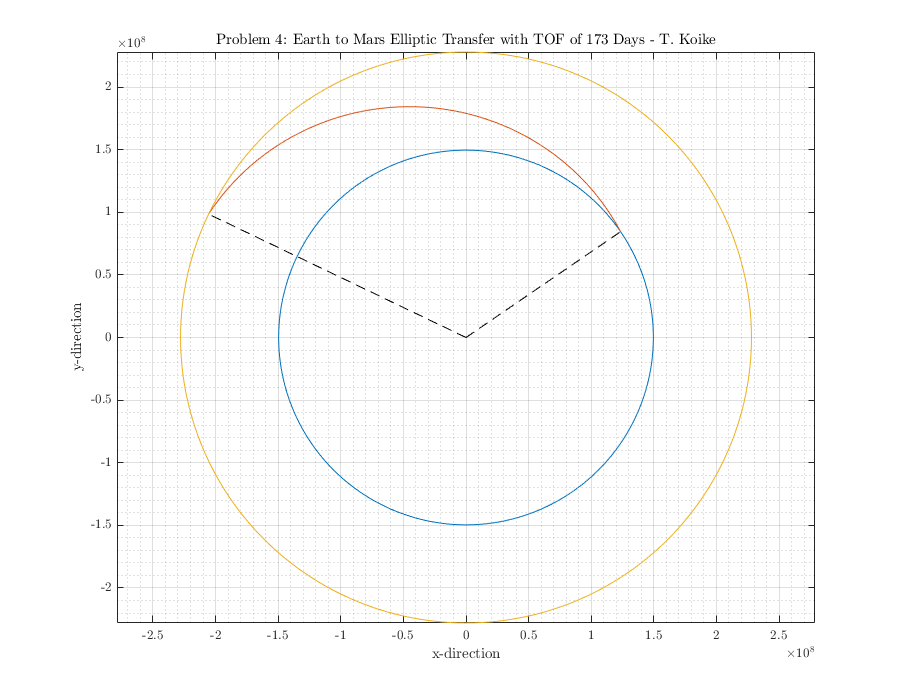

% Plotting

% Earth Orbit
angles = 0:360;
X_earth = earth.smao * cosd(angles); Y_earth = earth.smao * sind(angles);

% Transfer Orbit
angles = TA_dep:0.0001:TA_arr;
R_x = p ./ (1 + e * cosd(angles));
X_x = R_x .* cosd(angles); Y_x = R_x .* sind(angles);

% Mars Orbit
angles = 0:360;
X_mars = mars.smao * cosd(angles); Y_mars = mars.smao * sind(angles);

fig = figure("Renderer","painters","Position",[10 10 900 700]);
plot(X_earth, Y_earth)
hold on; grid on; grid minor; box on; axis equal;
plot(X_x, Y_x)
plot(X_mars, Y_mars)
plot([0, X_x(1)], [0, Y_x(1)], '--k')
plot([0, X_x(end)], [0, Y_x(end)], '--k')
hold off
title('Problem 4: Earth to Mars Elliptic Transfer with TOF of 173 Days - T. Koike')
xlabel('x-direction')
ylabel('y-direction')
saveas(fig, fullfile(fdir, 'p4_transfer.png'));